EX-001: hígado homogéneo con arreglo lineal en 2D

Este pipeline es el control rápido para la GUI. Usa kWaveArray, porque

kWaveTransducer solo funciona en 3D. El arreglo se modela como 16 elementos

rectangulares físicos. Se ejecuta un único caso base homogéneo.


clearvars;
close all;

1. Preparar carpetas, registro y versión de k-Wave

Cada experimento recibe una carpeta propia con setup, log, resultados y

figuras. Esta es la estructura que la GUI deberá generar y recuperar.

Esta ruta es explícita porque un Live Script puede ejecutarse desde una

copia temporal de MATLAB; por eso no usamos mfilename('fullpath').

Cambia solo dpb_root si guardas la carpeta DPB en otro lugar.

dpb_root = '/Users/miguelisidrobaez/Desktop/Academico/Organización/LIM/DPB';

fullfile une partes de una ruta sin escribir las barras manualmente.

repository_root = fullfile(dpb_root, 'dpb-qus-benchmark');
kwave_root = fullfile(dpb_root, 'Guia_adicional', 'k-wave-ii-develop');

isfolder comprueba que k-Wave esté instalado antes de usarlo.

assert(isfolder(kwave_root), 'No se encontró k-Wave: %s', kwave_root);

addpath permite llamar a las funciones de k-Wave en este script.

addpath(kwave_root);
import kwave.legacy.*

results_root = fullfile(repository_root, 'results');
experiment_id = 'EX-001_2D_linear_liver';
experiment_directory = fullfile(results_root, experiment_id);

Si la carpeta de resultados no existe, mkdir la crea junto con results.

Si ya existe, no se borra ni se modifica.

if ~isfolder(experiment_directory)
    mkdir(experiment_directory);
end
log_file = fullfile(experiment_directory, 'log.txt');
log_id = fopen(log_file, 'w');
cleanup_log = onCleanup(@() fclose(log_id));
writeLog(log_id, 'Configuración EX-001 creada.');

Configuración EX-001 creada.


2. Definir el medio hepático homogéneo base

Para este primer caso se conservan c=1595 m/s y rho=1060 kg/m^3 del

hígado. Como en los ejemplos introductorios de k-Wave, no se activa

atenuación ni no linealidad B/A. No se incluyen dispersores ni inclusiones:

el resultado es transmisión y patrón de haz, no imagen B-mode ni ecos.

Como en Initial_Value_Problems.mlx, la secuencia física que ejecuta

runCase es: malla -> medio -> fuente -> sensor -> simulación -> resultados.

La diferencia es que la fuente ya no es source.p0: es un arreglo temporal

source.p construido desde un transductor lineal con kWaveArray.

config = struct();
config.experiment_id = experiment_id;
config.dimension = '2D';
config.sound_speed_m_per_s = 1595;
config.density_kg_per_m3 = 1060;
config.center_frequency_hz = 1e6;
config.cycles = 3;
config.pressure_pa = 1e5;
config.points_per_wavelength = 4;
config.Nx = 256;
config.Ny = 192;
config.pml_size = 20;
config.cfl = 0.2;
config.number_elements = 16;
config.element_width_m = 0.45e-3;
config.element_kerf_m = 0.05e-3;
config.output_directory = experiment_directory;
save(fullfile(experiment_directory, 'setup_base.mat'), 'config');
writeLog(log_id, 'Medio hepático y setup base guardados.');

Medio hepático y setup base guardados.


3. Ejecutar el caso base

Solo se ejecuta un medio homogéneo sin atenuación. Así puedes verificar

primero malla, arreglo, receptor y propagación antes de añadir más física.

base = runCase(config, log_id);

Iniciando EX-001_2D_linear_liver.
Computing distributed source signal...
  calculating binary mask...                  completed in 0.026977s
  approximate size of source matrix:          94 KB (single precision)
  calculating element 1 grid weights...       completed in 0.002356s
  calculating element 1 distributed source... completed in 0.000964s
  calculating element 2 grid weights...       completed in 0.001976s
  calculating element 2 distributed source... completed in 0.00016s
  calculating element 3 grid weights...       completed in 0.001125s
  calculating element 3 distributed source... completed in 0.000211s
  calculating element 4 grid weights...       completed in 0.001332s
  calculating element 4 distributed source... completed in 0.000307s
  calculating element 5 grid weights...       completed in 0.001002s
  calculating element 5 distributed source... completed in 0.000117s
  calculating element 6 grid weights...       completed in 0.001132s
  calculating element 6 distr

Running k-Wave simulation...
  start time: 31-Aug-2026 17:47:34
  reference sound speed: 1595m/s
  dt: 50ns, t_end: 55us, time steps: 1101
  input grid size: 256 by 192 grid points (102.08 by 76.56mm)
  maximum supported frequency: 2MHz
  casting variables to single type...
  precomputation completed in 0.072159s
  starting time loop...
  estimated simulation time 3.5656s...
  simulation completed in 2.6798s
  total computation time 2.7545s
EX-001_2D_linear_liver completado.


save(fullfile(experiment_directory, 'results_2D.mat'), 'base', '-v7.3');

4. Verificar y visualizar los resultados

En un medio homogéneo, la llegada esperada es distancia/c.

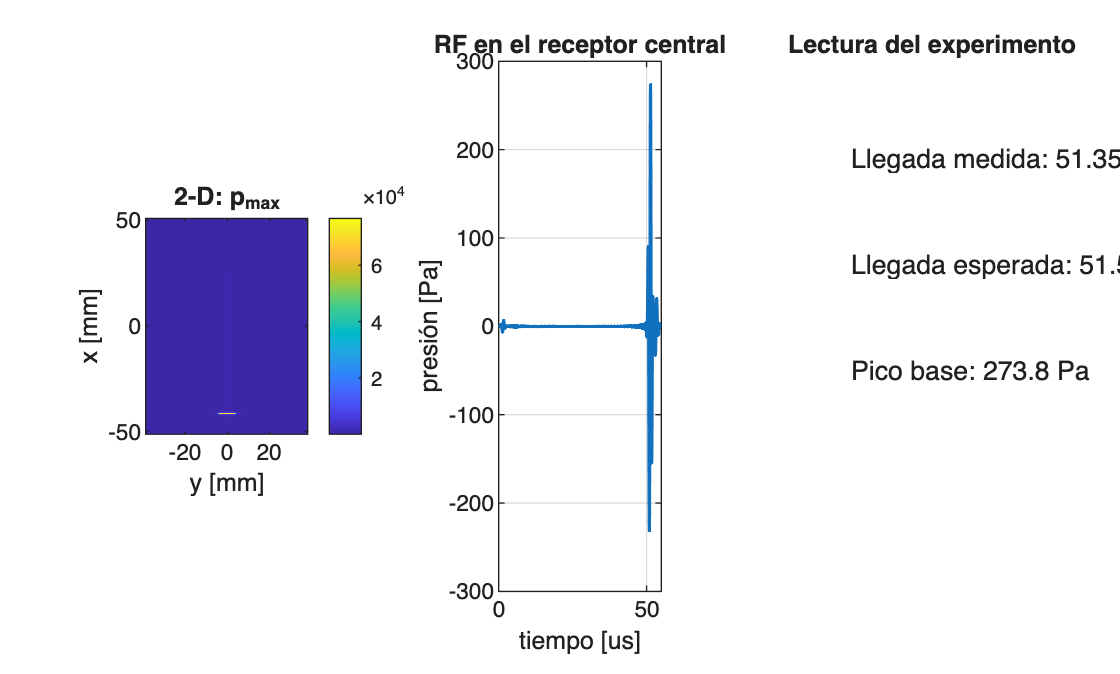

expected_arrival_s = base.distance_m / config.sound_speed_m_per_s;
arrival_error_s = abs(base.arrival_time_s - expected_arrival_s);
assert(arrival_error_s < 2 / config.center_frequency_hz, ...
    'La llegada no coincide con la distancia/c dentro de dos periodos.');

figure('Color', 'w');
tiledlayout(1, 3, 'TileSpacing', 'compact');
nexttile;
imagesc(base.y_mm, base.x_mm, base.p_max_field_pa); axis image; set(gca, 'YDir', 'normal');
xlabel('y [mm]'); ylabel('x [mm]'); title('2-D: p_{max}'); colorbar;
nexttile;
plot(base.time_s * 1e6, base.center_rf_pa, 'LineWidth', 1.2);
grid on; xlabel('tiempo [us]'); ylabel('presión [Pa]');
title('RF en el receptor central');
nexttile; axis off;
text(0, 0.82, sprintf('Llegada medida: %.2f us', base.arrival_time_s * 1e6));
text(0, 0.62, sprintf('Llegada esperada: %.2f us', expected_arrival_s * 1e6));
text(0, 0.42, sprintf('Pico base: %.1f Pa', base.peak_pressure_pa));
title('Lectura del experimento');
exportgraphics(gcf, fullfile(experiment_directory, 'results_2D.png'), 'Resolution', 180);

writeLog(log_id, 'Simulación completada y figura results_2D.png guardada.');

Simulación completada y figura results_2D.png guardada.


5. Interpretación para registrar después de ejecutar

El mapa p_max debe mostrar el haz hacia +x y la apertura lateral marcada

por los 16 elementos. El RF debe llegar alrededor de distancia/c. Si no

ocurre, revisar primero PML, tamaño de malla, máscara de arreglo y unidades.

6. Implementación física de cada caso 2-D

Esta función contiene las mismas secciones que tus ejemplos de problemas

de fuente temporal: malla, medio, fuente, máscara de sensor, PML, solver y

extracción de presión. Se declara al final para separar el flujo principal

de la construcción física de la simulación.


function result = runCase(config, log_id)
import kwave.legacy.*
writeLog(log_id, sprintf('Iniciando %s.', config.experiment_id));

La resolución se calcula desde lambda=c/f. Cuatro puntos por longitud de

onda siguen la recomendación conservadora para propagación homogénea.

dx_m = config.sound_speed_m_per_s / (config.center_frequency_hz * config.points_per_wavelength);
kgrid = kWaveGrid(config.Nx, dx_m, config.Ny, dx_m);
medium.sound_speed = config.sound_speed_m_per_s;
medium.density = config.density_kg_per_m3;
kgrid.makeTime(medium.sound_speed, config.cfl, 55e-6);

kWaveArray define la geometría del arreglo en metros y no en índices de

malla. Esto conserva el ancho y el kerf físicos aunque cambie dx.

karray = kWaveArray('BLITolerance', 0.05, 'UpsamplingRate', 10, 'SinglePrecision', true);
pitch_m = config.element_width_m + config.element_kerf_m;
source_x_m = kgrid.x_vec(config.pml_size + 5);
for element_index = 1:config.number_elements
    element_y_m = (element_index - (config.number_elements + 1) / 2) * pitch_m;
    karray.addRectElement([source_x_m, element_y_m], dx_m, config.element_width_m, 0);
end

La máscara representa los puntos de malla asociados al arreglo. La señal

se define una vez por elemento y se distribuye con los pesos BLI de k-Wave.

source.p_mask = karray.getArrayBinaryMask(kgrid);
source.p_mode = 'dirichlet';
burst = config.pressure_pa * toneBurst(1 / kgrid.dt, config.center_frequency_hz, config.cycles);
source.p = karray.getDistributedSourceSignal(kgrid, repmat(burst, config.number_elements, 1));

Se usa una línea distal como sensor para medir transmisión. No se usa el

mismo arreglo como receptor porque un medio homogéneo no devuelve eco útil.

receiver_x = config.Nx - config.pml_size - 5;
sensor.mask = zeros(config.Nx, config.Ny);
sensor.mask(receiver_x, config.pml_size + 1:config.Ny - config.pml_size) = 1;
sensor.record = {'p', 'p_max_all'};

La fuente y el sensor se colocan cinco nodos fuera de la PML interna. Así

la capa absorbente no altera la geometría física del experimento.

plotSetup2D(kgrid, source.p_mask, sensor.mask, config.output_directory);
sensor_data = kspaceFirstOrder2D(kgrid, medium, source, sensor, ...
    'PMLSize', config.pml_size, 'PMLInside', true, 'PlotSim', false, 'DataCast', 'single');

rf_data = gatherIfNeeded(sensor_data.p);
p_max_field = gatherIfNeeded(sensor_data.p_max_all);
[peak_pressure_pa, peak_index] = max(abs(rf_data(:)));
[~, time_index] = ind2sub(size(rf_data), peak_index);
result = struct('config', config, 'distance_m', (receiver_x - (config.pml_size + 5)) * dx_m, ...
    'time_s', kgrid.t_array, 'arrival_time_s', kgrid.t_array(time_index), ...
    'peak_pressure_pa', peak_pressure_pa, 'center_rf_pa', rf_data(round(end / 2), :), ...
    'p_max_field_pa', p_max_field, 'x_mm', kgrid.x_vec * 1e3, 'y_mm', kgrid.y_vec * 1e3);
writeLog(log_id, sprintf('%s completado.', config.experiment_id));
end

function writeLog(log_id, message)
fprintf(log_id, '%s %s\n', datestr(now, 'yyyy-mm-dd HH:MM:SS'), message);
fprintf('%s\n', message);
end

function value = gatherIfNeeded(value)
if isa(value, 'gpuArray'), value = gather(value); end
end

function plotSetup2D(kgrid, source_mask, sensor_mask, output_directory)
figure('Visible', 'off', 'Color', 'w');
imagesc(kgrid.y_vec * 1e3, kgrid.x_vec * 1e3, zeros(kgrid.Nx, kgrid.Ny));
axis image; set(gca, 'YDir', 'normal'); colormap(gray); hold on;
[source_x, source_y] = find(source_mask);
[sensor_x, sensor_y] = find(sensor_mask);
plot(kgrid.y_vec(source_y) * 1e3, kgrid.x_vec(source_x) * 1e3, 'r.', 'MarkerSize', 6);
plot(kgrid.y_vec(sensor_y) * 1e3, kgrid.x_vec(sensor_x) * 1e3, 'b.', 'MarkerSize', 6);
xlabel('y [mm]'); ylabel('x [mm]'); title('Previsualización 2-D: fuente roja, sensor azul');
legend('arreglo lineal', 'sensor de transmisión', 'Location', 'southoutside');
exportgraphics(gcf, fullfile(output_directory, 'setup_2D.png'), 'Resolution', 180);
close(gcf);
end